# Interactive MATLAB Lab 1.1: Is It a Solution?

In a Live Script, turn "choice" into a drop-down control.

choice = "exp(x^2)+1";   % Options: "exp(x^2)", "exp(x^2)+1", "3exp(x^2)", "x^2"

syms x

switch choice
    case "exp(x^2)"
        candidate = exp(x^2);
    case "exp(x^2)+1"
        candidate = exp(x^2) + 1;
    case "3exp(x^2)"
        candidate = 3*exp(x^2);
    case "x^2"
        candidate = x^2;
end

lhs = diff(candidate,x);
rhs = 2*x*candidate;
residual = simplify(lhs-rhs);
check = isequal(residual,sym(0));

disp("Differential equation: y' = 2xy")

Differential equation: y' = 2xy


disp("Proposed solution:")

Proposed solution:


disp(candidate)

$${\mathrm{e}}^{x^{2}}+1$$

disp("Left side y'(x):")

Left side y'(x):


disp(lhs)

$$2\,x\,{\mathrm{e}}^{x^{2}}$$

disp("Right side 2xy:")

Right side 2xy:


disp(rhs)

$$2\,x\,\left({\mathrm{e}}^{x^{2}}+1\right)$$

disp("Residual lhs-rhs:")

Residual lhs-rhs:


disp(residual)

$$-2\,x$$


if check
    disp("YES - the proposed function satisfies the differential equation.")
else
    disp("NO - the proposed function does not satisfy the differential equation.")
end

NO - the proposed function does not satisfy the differential equation.


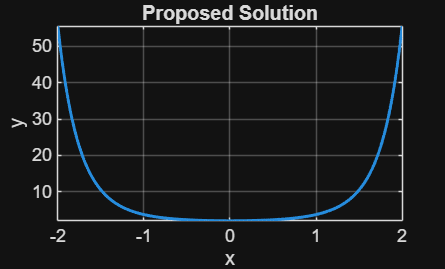


figure
fplot(candidate,[-2 2],'LineWidth',1.5)
grid on
xlabel('x')
ylabel('y')
title('Proposed Solution')